# plotIsotropicBoundary (Linux)

Initializing, and extracting data

clear all;
% h5FileStr = '/media/nithin/PFISR_002_006/PFISR Processed/Event_List/EnergeticElectronArc/20080326.001_bc_15sec-energyFlux.h5';
h5FileStr = '/media/nithin/PFISR_002_006/PFISR Processed/Event_List/EnergeticElectronArc/20101018.001_bc_2min-energyFlux.h5';
% h5FileStr = 'G:\My Drive\Research\Projects\Paper 2\Data\Temp\20101018.001_bc_2min-energyFlux.h5';
omniH5FileStr = '/home/nithin/Documents/git-repos/LargeFiles/omni/omni.h5';


Calculating input 


magFieldModel = 7; % TSY 1996
% magFieldModel = 11; % TSY04 Storm

Calculating Equator

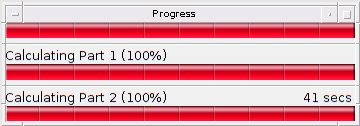

tic
[status] = create_magneticFieldProjection_hdf5(magFieldModel,h5FileStr,omniH5FileStr,'options',[1,0,0,1,0],'pixels',64);

toc

Elapsed time is 28881.989860 seconds.


Plotting countours